% Author: Michael Noyce
% Plotting the output and calculating the error of the STM32 module 

Textfile = load("STM32Output.txt")

Textfile = 	1.0e+-3 *

    0.0406
    0.0092
    0.0280
    0.0245
    0.0634
    0.1074
    0.1485
    0.0228
    0.0374
    0.0333


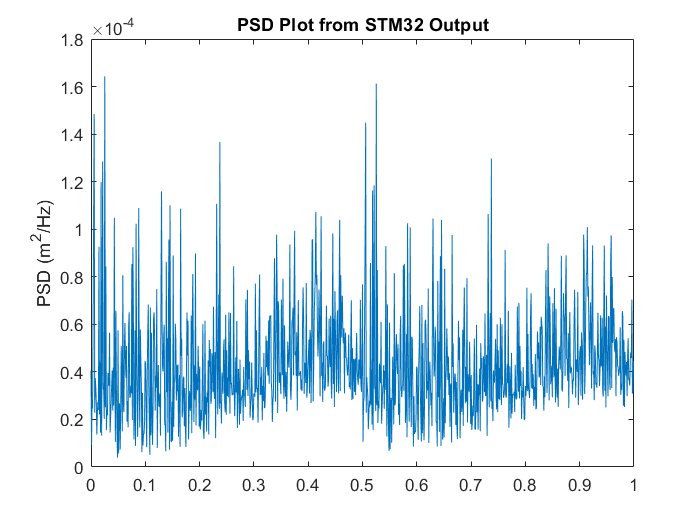

writematrix(Textfile, "STM32Output.csv");
STM32Output = readtable("STM32Output.csv");

PSD = STM32Output{:, 1};
%N = length(PSD);
%fs =2; 
%f = fs*(0:(N/2))/N;

%Plot output
plot(f(1, 1:1024), PSD);
ylabel("PSD (m^2/Hz)"); 
title("PSD Plot from STM32 Output")